% 
% q=0.000000000000000000016
% q1=-0.000000000000000000016
% x0=0
% y0=0
% %Posicion vector inicial
% 
% %Posicion
% x1=5
% y1=5
% 
% k=9000000000 
% dist_x=x-x0
% dist_y=y-y0
% 
% dist_x1=x-x1
% dist_y1=y-y1
% denom1=(dist_x^2+dist_y^2)^1.5
% denom2=(dist_x1^2+dist_y1^2)^1.5


Campos electricos

% num_E1=q*k
% num_E2=q1*k
% 
% %Campo electrico (componentes primer carga)
% ex=num_E1*dist_x/denom1
% ey=num_E1*dist_y/denom1
% 
% %Campo electrico (componentes segunda carga)
% ex1=num_E2*dist_x1/denom2
% ey1=num_E2*dist_y/denom2
% 
% ex=ex+ex1
% ey=ey+ey1
% %quiver (x,y,ex,ey) 


Electric field Map

n=80

n = 80

x=linspace(-.5,.5,n);
y=linspace(-.5,.5,n);
[X,Y]=meshgrid(x,y);
%plot(X,Y,'*r')
q=input('Introduce el valor de la primer carga puntual:');
q1=input('Introduce el valor de la segunda carga puntual:');
x0=0;
y0=0;
x3=X;
y3=Y;
x1=.4;
y1=0;
k=9000000000 

k = 9.0000e+09

dist_x=x3-x0

dist_x =    -0.5000   -0.4873   -0.4747   -0.4620   -0.4494   -0.4367   -0.4241   -0.4114   -0.3987   -0.3861   -0.3734   -0.3608   -0.3481   -0.3354   -0.3228   -0.3101   -0.2975   -0.2848   -0.2722   -0.2595   -0.2468   -0.2342   -0.2215   -0.2089   -0.1962   -0.1835   -0.1709   -0.1582   -0.1456   -0.1329   -0.1203   -0.1076   -0.0949   -0.0823   -0.0696   -0.0570   -0.0443   -0.0316   -0.0190   -0.0063    0.0063    0.0190    0.0316    0.0443    0.0570    0.0696    0.0823    0.0949    0.1076    0.1203
   -0.5000   -0.4873   -0.4747   -0.4620   -0.4494   -0.4367   -0.4241   -0.4114   -0.3987   -0.3861   -0.3734   -0.3608   -0.3481   -0.3354   -0.3228   -0.3101   -0.2975   -0.2848   -0.2722   -0.2595   -0.2468   -0.2342   -0.2215   -0.2089   -0.1962   -0.1835   -0.1709   -0.1582   -0.1456   -0.1329   -0.1203   -0.1076   -0.0949   -0.0823   -0.0696   -0.0570   -0.0443   -0.0316   -0.0190   -0.0063    0.0063    0.0190    0.0316    0.0443    0.0570    0.0696    0.0823    0.0949    0.1076

dist_y=y3-y0

dist_y =    -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000   -0.5000
   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873   -0.4873


dist_x1=x3-x1;
dist_y1=y3-y1;

denom1=(dist_x.^2+dist_y.^2).^1.5;
denom2=(dist_x1.^2+dist_y1.^2).^1.5;

num_E1=q*k;
num_E2=q1*k;

%Campo electrico (componentes primer carga)
ex=num_E1*dist_x./denom1;
ey=num_E1*dist_y./denom1;

%Campo electrico (componentes segunda carga)
ex1=num_E2*dist_x1./denom2;
ey1=num_E2*dist_y1./denom2;
% Ex=(ex./u)+(ex1./v);
% Ey=(ey./u)+(ey1./v);
Ex=(ex+ex1);
Ey=(ey+ey1);
mE=sqrt(Ex.^2+Ey.^2)

mE = 	1.0e+14 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002  


hold on
% quiver(X,Y,Ex,Ey,'k','autoscalefactor',.5)
axis equal
% plot(x0,y0,'*r','Markersize',30)
% plot(x1,y1,'*k','Markersize',30)
% Ef=streamslice(X,Y,Ex,Ey)
% 
% Ef=set(Ef,'color','r')

subplot(1,3,1)
hold on
plot(x0,y0,'or','Markersize',5)
plot(x1,y1,'om','Markersize',5)
%quiver(X,Y,Ex,Ey,'k','autoscalefactor',5)
quiverC2D(X,Y,Ex./abs(Ex),Ey./abs(Ey),1)
axis equal

subplot(1,3,2)
hold on
Ef=streamslice(X,Y,Ex,Ey)

Ef =   112×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


plot(x0,y0,'*r','Markersize',30)
plot(x1,y1,'*m','Markersize',30)
axis equal

subplot(1,3,3)
hold on
Ef=streamslice(X,Y,Ex,Ey)

Ef =   112×1 Line array:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


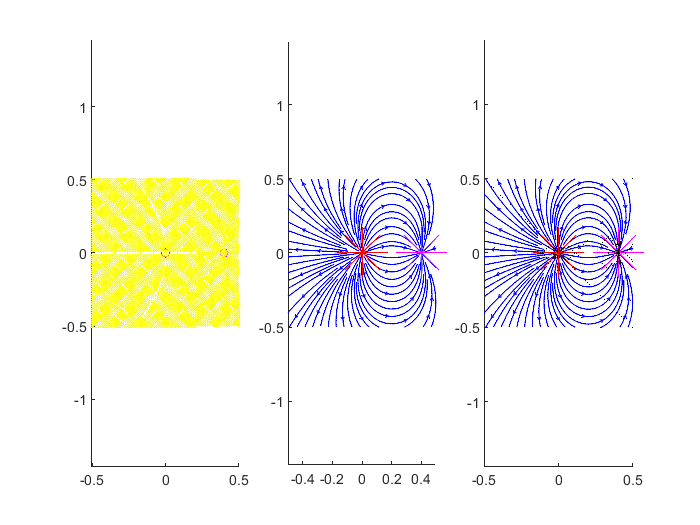

plot(x0,y0,'*r','Markersize',30)
plot(x1,y1,'*m','Markersize',30)
quiver(X,Y,Ex,Ey,'k','autoscalefactor',5)
axis equal